close all
clear
clc

## 准备工作

定义很宽的时间采样点

t0 = [-10:0.05:10]';

定义阶跃信号

u0 = double(t0>0);

定义单边正弦信号

x0 = sin(2*pi*t0).*u0;

定义指数信号

y0 = exp(-t0).*u0;

## 完成题目要求

定义时间范围

tLim = [-1,2];

截取题目所要求的时间范围的样本

idx = (t0>=tLim(1)&t0<=tLim(2));
t = t0(idx);
x = x0(idx);
y = y0(idx);

直接计算z1, z4和z5

z1 = 2*x;
z4 = x + y;
z5 = x.*y;

z2对x右移，相当于对t增加后进行截取

t2 = t0+0.5;
idx = (t2>=tLim(1)&t2<=tLim(2));
t2 = t2(idx);
z2 = x0(idx);

z3对x压缩，相当于对t压缩后进行截取

t3 = t0/2;
idx = (t3>=tLim(1)&t3<=tLim(2));
t3 = t3(idx);
z3 = x0(idx);

绘图：x和z1、z2、z3

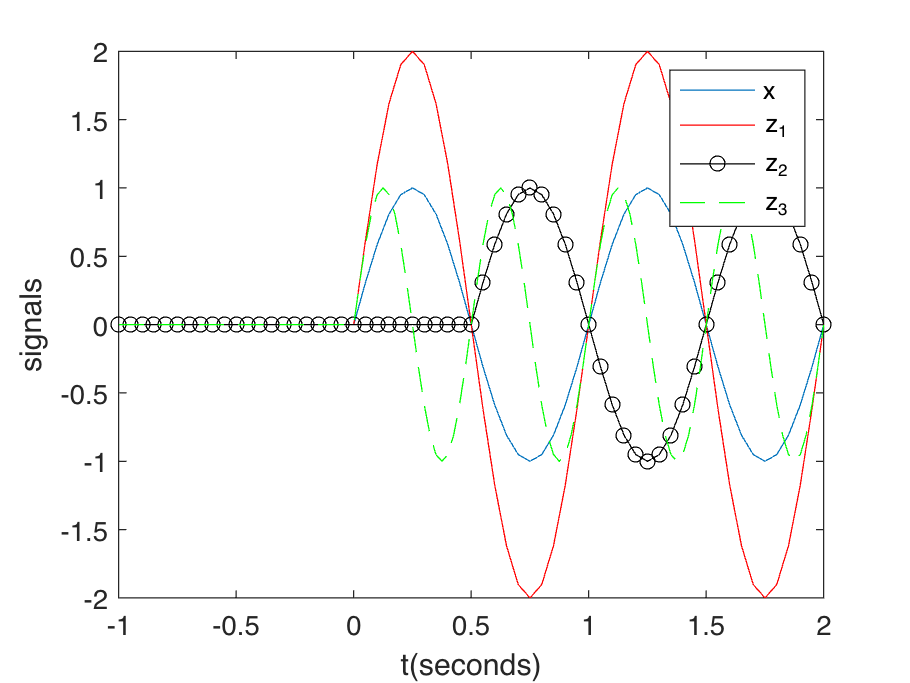

figure;
hold on
plot(t,x);
plot(t,z1,'r');
plot(t2,z2,'k-o');
plot(t3,z3,'g--');
xlabel('t(seconds)');
ylabel('signals');
legend('x','z_1','z_2','z_3');
box on

绘图：z4和z5，以及x和y作参考

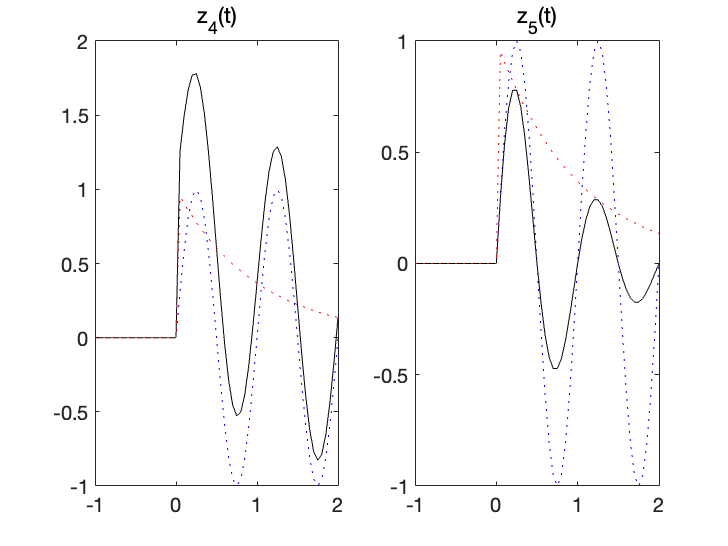

figure;
subplot(1,2,1);
plot(t,z4,'k',t,x,'b:',t,y,'r:');
title('z_4(t)');
subplot(1,2,2);
plot(t,z5,'k',t,x,'b:',t,y,'r:');
title('z_5(t)');